# Image Category

## Load Images Dataset Folder

imgDs = imageDatastore('C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET', ...
    'FileExtensions', {'.jpg'}, ...
    'IncludeSubfolders',true, ...
    'LabelSource',"foldernames")

imgDs =   ImageDatastore with properties:

                       Files: {
                              ' ...\barbecued_red-ThaiFoodDataset-004.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-006.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-007.jpg'
                               ... and 9497 more
                              }
                     Folders: {
                              ' ...\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET'
                              }
                      Labels: [barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice ... and 9497 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
       

## Dataset Analysis

### Show some sample Steak image

% steak = find(imgDs.Labels == 'thai_papaya_salad')

%figure
%imshow(readimage(imgDs,steak))

### Count the number of data for each class

tbl = countEachLabel(imgDs)

tbl = 38×2 table
                    Label                     Count
    ______________________________________    _____

    barbecued_red_pork_in_sauce_with_rice      250 
    caesar_salad                               250 
    charcoal-boiled_pork_neck                  250 
    chow_mein                                  250 
    coconut_milk_soup                          250 
    crispy_pork_with_kale_with_rice            250 
    fried_chicken_with_rice                    250 
    fried_mussel_pancakes                      250 
    fried_pork_with_rice                       250 
    fried_rice                                 250 
    green_curry                                250 
    hamburger                                  250 
    hot_and_sour_fish_and_vegetable_ragout     250 
    kebab                                      250 
    khao_soi                                   250 
    noodles                   

classTypes = tbl{:,1}

classTypes = 38×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     caesar_salad 
     charcoal-boiled_pork_neck 
     chow_mein 
     coconut_milk_soup 
     crispy_pork_with_kale_with_rice 
     fried_chicken_with_rice 
     fried_mussel_pancakes 
     fried_pork_with_rice 
     fried_rice 
     green_curry 
     hamburger 
     hot_and_sour_fish_and_vegetable_ragout 
     kebab 
     khao_soi 
     noodles 
     noodles_with_fish_curry 
     noodles_without_soup 
     omelette 
     onion_rings 
     pad_see_ew 
     pad_thai 
     peking_duck 
     pizza 
     rice_crispy_pork 
     rice_topped_with_stir_fried_meat_and_basil 
     spaghetti_bolognese 
     spaghetti_carbonara 
     spicy_chicken_salad_with_rice 
     spicy_stir_fried_pork_with_red_curry_paste 


## Split the dataset for both training and testing set

[trainingSet, testSet] = splitEachLabel(imgDs, 0.7, 'randomize');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;
trainingSet.Files{trainingLabels, 1};
% Show the size and the files of the training set
size(trainingSet.Files)

ans =         6650           1


trainingSet.Files

ans = 6650×1 cell array
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-004.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-006.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-007.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-014.jpg'}
    {'C:

# **Classifier Evaluation**

## METHOD 1: FEATURE MATCHING

### Train the training dataset to an Excel file!

evaluationExcelFilePath = './evaluate/eval_feature_matching_model.xlsx';
portion = 100

portion = 100


totalFiles = size(trainingSet.Files) - 1

totalFiles =         6649           0


progression = 0;
for i = 1 : portion : totalFiles
    
    T = table();
    
    for j = 0 : min(portion - 1, totalFiles - i)
       
        [filepath,name,ext] = fileparts(trainingSet.Files{i + j, 1});
        paths = split(filepath, '\');
        className = cell2mat(paths(end));
        % trainAnImage(evaluationExcelFilePath, readimage(imgDs, i), trainingSet.Files{i, 1}, className);
    
        [meanRed, meanGreen, meanBlue, meanGrayscale, bwArea, entropyVal, energy, contrast, correlation, homogeneity, sobelArea, cannyArea] = extractFeaturesFromAnImage(readimage(trainingSet, i + j));

        path = convertCharsToStrings(trainingSet.Files{i + j, 1});
        class = {className};
        newTableRow = table(path, class, meanRed, meanGreen, meanBlue, meanGrayscale, bwArea, entropyVal, energy, contrast, correlation, homogeneity, sobelArea, cannyArea);
        T = [T; newTableRow];
        
        progression = progression + 1;
        
        if progression >= totalFiles
            break
        end
    end
    
    [string(progression) '/' string(totalFiles)] 
    % featureArray = [path className meanRed meanGreen meanBlue meanGrayscale bwArea entropyVal energy contrast correlation homogeneity sobelArea cannyArea]
    writetable(T, evaluationExcelFilePath, 'WriteMode', 'Append', 'WriteVariableNames',i == 1,'WriteRowNames',false);
end

ans = 1×4 string array
    "100"    "/"    "6649"    "0"


ans = 1×4 string array
    "200"    "/"    "6649"    "0"


ans = 1×4 string array
    "300"    "/"    "6649"    "0"


ans = 1×4 string array
    "400"    "/"    "6649"    "0"


ans = 1×4 string array
    "500"    "/"    "6649"    "0"


ans = 1×4 string array
    "600"    "/"    "6649"    "0"


ans = 1×4 string array
    "700"    "/"    "6649"    "0"


ans = 1×4 string array
    "800"    "/"    "6649"    "0"


ans = 1×4 string array
    "900"    "/"    "6649"    "0"


ans = 1×4 string array
    "1000"    "/"    "6649"    "0"


ans = 1×4 string array
    "1100"    "/"    "6649"    "0"


ans = 1×4 string array
    "1200"    "/"    "6649"    "0"


ans = 1×4 string array
    "1300"    "/"    "6649"    "0"


ans = 1×4 string array
    "1400"    "/"    "6649"    "0"


ans = 1×4 string array
    "1500"    "/"    "6649"    "0"


ans = 1×4 string array
    "1600"    "/"    "6649"    "0"


ans = 1×4 string array
    "1700"    "/"    "6649"    "0"


ans = 1×4 string array
    "1800"    "/"    "6649"    "0"


ans = 1×4 string array
    "1900"    "/"    "6649"    "0"


ans = 1×4 string array
    "2000"    "/"    "6649"    "0"


ans = 1×4 string array
    "2100"    "/"    "6649"    "0"


ans = 1×4 string array
    "2200"    "/"    "6649"    "0"


ans = 1×4 string array
    "2300"    "/"    "6649"    "0"


ans = 1×4 string array
    "2400"    "/"    "6649"    "0"


ans = 1×4 string array
    "2500"    "/"    "6649"    "0"


ans = 1×4 string array
    "2600"    "/"    "6649"    "0"


ans = 1×4 string array
    "2700"    "/"    "6649"    "0"


ans = 1×4 string array
    "2800"    "/"    "6649"    "0"


ans = 1×4 string array
    "2900"    "/"    "6649"    "0"


ans = 1×4 string array
    "3000"    "/"    "6649"    "0"


ans = 1×4 string array
    "3100"    "/"    "6649"    "0"


ans = 1×4 string array
    "3200"    "/"    "6649"    "0"


ans = 1×4 string array
    "3300"    "/"    "6649"    "0"


ans = 1×4 string array
    "3400"    "/"    "6649"    "0"


ans = 1×4 string array
    "3500"    "/"    "6649"    "0"


ans = 1×4 string array
    "3600"    "/"    "6649"    "0"


ans = 1×4 string array
    "3700"    "/"    "6649"    "0"


ans = 1×4 string array
    "3800"    "/"    "6649"    "0"


ans = 1×4 string array
    "3900"    "/"    "6649"    "0"


ans = 1×4 string array
    "4000"    "/"    "6649"    "0"


ans = 1×4 string array
    "4100"    "/"    "6649"    "0"


ans = 1×4 string array
    "4200"    "/"    "6649"    "0"


ans = 1×4 string array
    "4300"    "/"    "6649"    "0"


ans = 1×4 string array
    "4400"    "/"    "6649"    "0"


ans = 1×4 string array
    "4500"    "/"    "6649"    "0"


ans = 1×4 string array
    "4600"    "/"    "6649"    "0"


ans = 1×4 string array
    "4700"    "/"    "6649"    "0"


ans = 1×4 string array
    "4800"    "/"    "6649"    "0"


ans = 1×4 string array
    "4900"    "/"    "6649"    "0"


ans = 1×4 string array
    "5000"    "/"    "6649"    "0"


ans = 1×4 string array
    "5100"    "/"    "6649"    "0"


ans = 1×4 string array
    "5200"    "/"    "6649"    "0"


ans = 1×4 string array
    "5300"    "/"    "6649"    "0"


ans = 1×4 string array
    "5400"    "/"    "6649"    "0"


ans = 1×4 string array
    "5500"    "/"    "6649"    "0"


ans = 1×4 string array
    "5600"    "/"    "6649"    "0"


ans = 1×4 string array
    "5700"    "/"    "6649"    "0"


ans = 1×4 string array
    "5800"    "/"    "6649"    "0"


ans = 1×4 string array
    "5900"    "/"    "6649"    "0"


ans = 1×4 string array
    "6000"    "/"    "6649"    "0"


ans = 1×4 string array
    "6100"    "/"    "6649"    "0"


ans = 1×4 string array
    "6200"    "/"    "6649"    "0"


ans = 1×4 string array
    "6300"    "/"    "6649"    "0"


ans = 1×4 string array
    "6400"    "/"    "6649"    "0"


ans = 1×4 string array
    "6500"    "/"    "6649"    "0"


ans = 1×4 string array
    "6600"    "/"    "6649"    "0"


ans = 1×4 string array
    "6649"    "/"    "6649"    "0"


### Test the classifier by iterating thru each testing example and predict some food

excelTable = readtable('./evaluate/eval_feature_matching_model.xlsx');
table2array(excelTable(:, 1));

predictedLabels = [];
for z = 1:size(testSet.Files)
    image = imread(testSet.Files{z, 1});
    [matchingImagePath, distance, className] = recogizeByFeatures(evaluationExcelFilePath, image);
    
    predictedLabels = [predictedLabels; className];
end


### EVALUATE & SUMMARY

testPrediction1 = categorical(predictedLabels)

testPrediction1 = 2850×1 categorical array
     rice_crispy_pork 
     green_curry 
     fried_chicken_with_rice 
     hamburger 
     barbecued_red_pork_in_sauce_with_rice 
     hamburger 
     caesar_salad 
     spicy_stir_fried_pork_with_red_curry_paste 
     omelette 
     steamed_rice_roll 
     hamburger 
     rice_crispy_pork 
     steamed_chicken_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     coconut_milk_soup 
     fried_pork_with_rice 
     fried_pork_with_rice 
     hot_and_sour_fish_and_vegetable_ragout 
     steamed_rice_roll 
     noodles_without_soup 
     omelette 
     spicy_stir_fried_pork_with_red_curry_paste 
     spicy_stir_fried_pork_with_red_curry_paste 
     pad_see_ew 
     onion_rings 
     rice_crispy_pork 
     caesar_salad 
     noodles_without_soup 
     omelette 
     peking_duck 


save('./evaluate/method1_feature_similarity_prediction.mat', 'testPrediction1')

% Get the known labels
testLabels = testSet.Labels;
save('./evaluate/method1_feature_similarity_groundtruth.mat', 'testLabels')

% Tabulate the results using a confusion matrix.
confMat1 = confusionmat(testLabels, testPrediction1)

confMat1 = 10×30
     5     4     2     1     3     0     4     0     4     2     1     4     1     0     0     0     1     5     3     3     3     1     1     1    11     2     0     1     0     4
     2     4     2     1     2     1     2     4     1     0     2     7     1     0     2     1     1     2     3     0     2     2     0     2     2     2     1     1     0     2
     2     2     6     1     2     0     1     4     0     2     2     0     0     3     2     1     7     1     0     0     1     1     0     2     2     1     2     1     5     0
     0     1     1     6     1     0     1     3     1     3     2     2     1     5     4     0     1     1     3     3     0     4     0     1     0     1     2     0     7     1
     1     2     1     2     1     2     3     2     1     0     3     2     1     0     0     3     1     3     5     3     2     0     2     1     2     7     2     1     2     4
     2     1     0     1     0    19     2     0     6     3     1     0     3

save('./evaluate/method1_feature_similarity_confusion.mat', 'confMat1')

% Convert confusion matrix into percentage form
percentConfMat1 = bsxfun(@rdivide,confMat1,sum(confMat1,2))

percentConfMat1 = 10×30
    0.0667    0.0533    0.0267    0.0133    0.0400         0    0.0533         0    0.0533    0.0267    0.0133    0.0533    0.0133         0         0         0    0.0133    0.0667    0.0400    0.0400    0.0400    0.0133    0.0133    0.0133    0.1467    0.0267         0    0.0133         0    0.0533
    0.0267    0.0533    0.0267    0.0133    0.0267    0.0133    0.0267    0.0533    0.0133         0    0.0267    0.0933    0.0133         0    0.0267    0.0133    0.0133    0.0267    0.0400         0    0.0267    0.0267         0    0.0267    0.0267    0.0267    0.0133    0.0133         0    0.0267
    0.0267    0.0267    0.0800    0.0133    0.0267         0    0.0133    0.0533         0    0.0267    0.0267         0         0    0.0400    0.0267    0.0133    0.0933    0.0133         0         0    0.0133    0.0133         0    0.0267    0.0267    0.0133    0.0267    0.0133    0.0667         0
         0    0.0133    0.0133    0.0800    0.0133         0    0.0133   

averageAccuracy1 = mean(diag(percentConfMat1))

averageAccuracy1 = 0.1189


% Find the precision
for i = 1:size(confMat1,1)
    precision1(i) = confMat1(i,i) / sum(confMat1(i, :));
end

% Find the recall
for i = 1:size(confMat1,1)
    recall1(i) = confMat1(i,i) / sum(confMat1(:, i));
end
precision1

precision1 = 1×30
    0.0667    0.0533    0.0800    0.0800    0.0133    0.2533    0.1867    0.0133    0.2800    0.1067    0.0800    0.0267    0.0933    0.5333    0.0533    0.1200    0.0933    0.0800    0.0533    0.0667    0.4667    0.0533    0.0667    0.1333    0.0800    0.0800    0.0133    0.0933    0.1200    0.3333


recall1

recall1 = 1×30
    0.0658    0.0563    0.0845    0.0882    0.0159    0.2836    0.1667    0.0145    0.2727    0.1127    0.1132    0.0250    0.1250    0.5263    0.0488    0.1125    0.1273    0.0682    0.0714    0.0704    0.3535    0.0556    0.0649    0.1429    0.0811    0.0723    0.0135    0.1111    0.1011    0.2632



% Find the F1 SCORE
f1Score1 = (2 .* precision1 .* recall1) ./ (precision1 + recall1)

f1Score1 = 1×30
    0.0662    0.0548    0.0822    0.0839    0.0145    0.2676    0.1761    0.0139    0.2763    0.1096    0.0938    0.0258    0.1069    0.5298    0.0510    0.1161    0.1077    0.0736    0.0611    0.0685    0.4023    0.0544    0.0658    0.1379    0.0805    0.0759    0.0134    0.1014    0.1098    0.2941



summaryA = table(classTypes, precision1', recall1', f1Score1')

summaryA = 38×4 table
                  classTypes                    Var2        Var3        Var4  
    ______________________________________    ________    ________    ________

    barbecued_red_pork_in_sauce_with_rice     0.066667    0.065789    0.066225
    caesar_salad                              0.053333    0.056338    0.054795
    charcoal-boiled_pork_neck                     0.08    0.084507    0.082192
    chow_mein                                     0.08    0.088235    0.083916
    coconut_milk_soup                         0.013333    0.015873    0.014493
    crispy_pork_with_kale_with_rice            0.25333     0.28358     0.26761
    fried_chicken_with_rice                    0.18667     0.16667      0.1761
    fried_mussel_pancakes                     0.013333    0.014493    0.013889
    fried_pork_with_rice                          0

writetable(summaryA, "./evaluate/result_method1_feature_similarity.xls")

## METHOD 2: DEEP LEARNING + SVM

### Train the training dataset

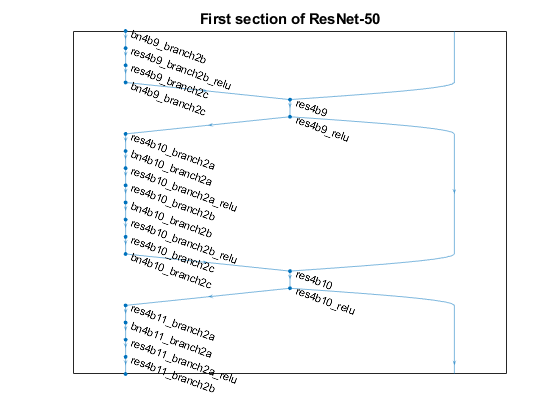



net = resnet101();

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);


net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


numel(net.Layers(end).ClassNames)

ans = 1000

## Preparing Training and Testing set

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize

imageSize = 1×3
   224   224     3


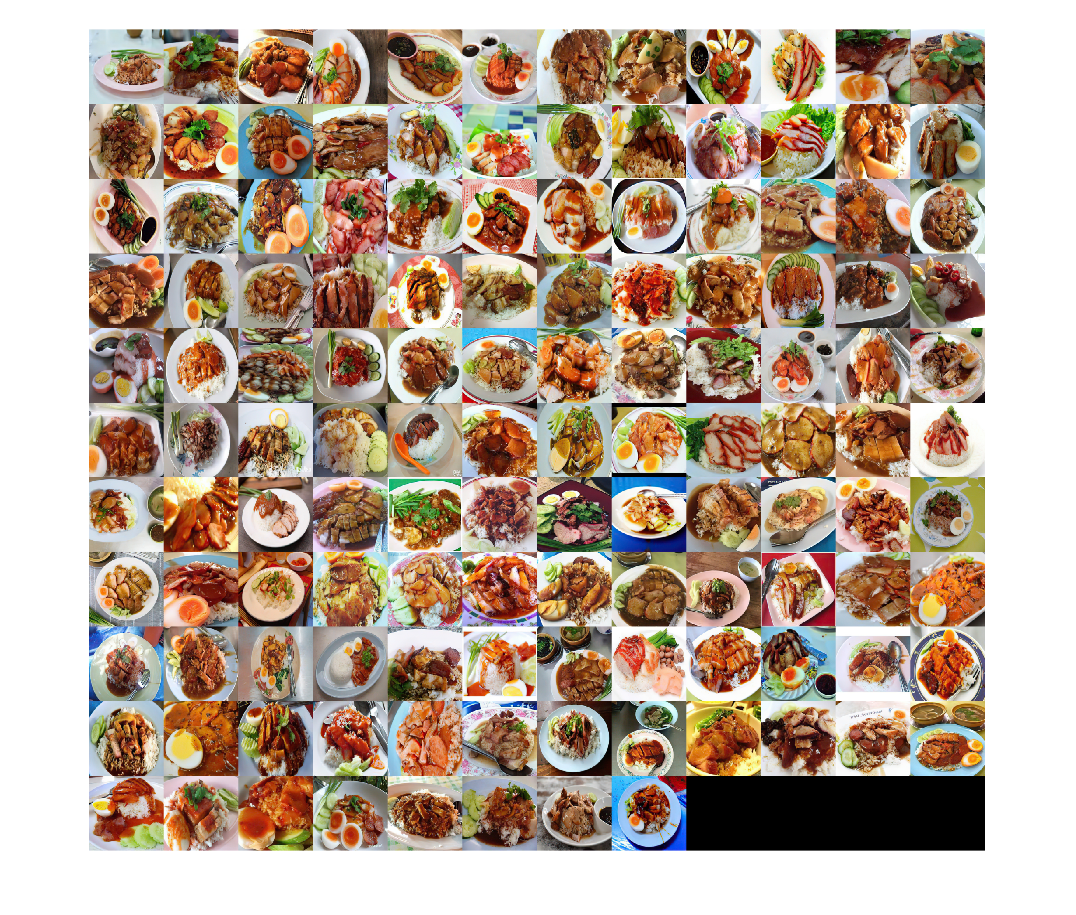


trainingSet.ReadFcn = @scaleimage;
testSet.ReadFcn = @scaleimage;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, "OutputSizeMode", "centercrop");
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, "OutputSizeMode", "centercrop" );

minibatch = read(augmentedTrainingSet);
imshow(imtile(minibatch.input))

%% Get the activation of the last fully-connected layer
featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels

trainingLabels = 6650×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_w


% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.

classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');
save('./evaluate/method2_CNN_prediction.mat', 'predictedLabels')


% Get the known labels
testLabels = testSet.Labels;
save('./evaluate/method2_CNN_groundtruth.mat', 'testLabels')

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels)

confMat = 10×30
    22     0     0     0     0     0    11     1     0     2     0     0     1     0     1     1     0     1     0     0     3     0     5     0    19     0     0     0     0     3
     0    55     0     0     0     1     1     1     0     3     0     1     0     0     1     0     0     0     0     0     2     1     2     0     0     1     0     1     0     2
     0     0    64     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     3     0     0     0     0     0     1     0
     0     0     0    50     0     0     0     4     0     0     0     0     2     0     1     0     0     0     0     0     4     6     0     0     0     0     0     1     0     0
     0     0     0     0    47     2     0     0     0     1     3     0     4     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0    62     0     0     0     0     0     0     0 

save('./evaluate/method2_CNN_confusion.mat', 'confMat')

% Convert confusion matrix into percentage form
percentConfMat = bsxfun(@rdivide,confMat,sum(confMat,2))

percentConfMat = 10×30
    0.2933         0         0         0         0         0    0.1467    0.0133         0    0.0267         0         0    0.0133         0    0.0133    0.0133         0    0.0133         0         0    0.0400         0    0.0667         0    0.2533         0         0         0         0    0.0400
         0    0.7333         0         0         0    0.0133    0.0133    0.0133         0    0.0400         0    0.0133         0         0    0.0133         0         0         0         0         0    0.0267    0.0133    0.0267         0         0    0.0133         0    0.0133         0    0.0267
         0         0    0.8533         0         0         0         0    0.0133         0         0         0         0         0         0         0         0         0         0    0.0133         0         0         0    0.0400         0         0         0         0         0    0.0133         0
         0         0         0    0.6667         0         0         0    


averageAccuracy = mean(diag(percentConfMat))

averageAccuracy = 0.7460


% Find the precision
for i = 1:size(confMat,1)
    precision(i) = confMat(i,i) / sum(confMat(i, :));
end

% Find the recall
for i = 1:size(confMat,1)
    recall(i) = confMat(i,i) / sum(confMat(:, i));
end
precision

precision = 1×30
    0.2933    0.7333    0.8533    0.6667    0.6267    0.8267    0.8133    0.8000    0.5867    0.7600    0.8133    0.8933    0.9600    0.8800    0.8400    0.6933    0.4533    0.3867    0.6133    0.9867    0.9467    0.8400    0.8533    0.9067    0.3467    0.6533    0.8133    0.8800    0.7333    0.7067


recall

recall = 1×30
    0.6875    0.9649    0.8649    0.9091    0.9400    0.8267    0.4485    0.6186    0.8980    0.6628    0.8472    0.9437    0.6486    0.9296    0.7875    0.8125    0.8947    0.8056    0.8070    0.9610    0.5221    0.6563    0.6275    0.9444    0.5200    0.8448    0.7922    0.9041    0.8462    0.6543



% Find the F1 SCORE
f1Score = (2 .* precision .* recall) ./ (precision + recall)

f1Score = 1×30
    0.4112    0.8333    0.8591    0.7692    0.7520    0.8267    0.5782    0.6977    0.7097    0.7081    0.8299    0.9178    0.7742    0.9041    0.8129    0.7482    0.6018    0.5225    0.6970    0.9737    0.6730    0.7368    0.7232    0.9252    0.4160    0.7368    0.8026    0.8919    0.7857    0.6795



summaryB = table(classTypes, precision', recall', f1Score')

summaryB = 38×4 table
                  classTypes                   Var2       Var3       Var4  
    ______________________________________    _______    _______    _______

    barbecued_red_pork_in_sauce_with_rice     0.29333     0.6875    0.41121
    caesar_salad                              0.73333    0.96491    0.83333
    charcoal-boiled_pork_neck                 0.85333    0.86486    0.85906
    chow_mein                                 0.66667    0.90909    0.76923
    coconut_milk_soup                         0.62667       0.94      0.752
    crispy_pork_with_kale_with_rice           0.82667    0.82667    0.82667
    fried_chicken_with_rice                   0.81333    0.44853     0.5782
    fried_mussel_pancakes                         0.8    0.61856    0.69767
    fried_pork_with_rice                      0.58667    0.89796    0.70968
    f

writetable(summaryB, "./evaluate/result_method2_CNN.xls")

save('./evaluate/final_eval_session')